close all
clear variables

spol = 299792458; % Скорость света в м/с
lambda_emit = 656.28 - 1; % Длина испущенной волны

spectra = importdata ("spectra.csv"); 
lambdaStart = importdata ("lambda_start.csv");
lambdaDelta = importdata ("lambda_delta.csv");
starNames = importdata ("star_names.csv");

number_of_measurements = size (spectra, 1);

number_of_stars = size (spectra, 2);

lambda_end = lambdaStart + (number_of_measurements - 1) * lambdaDelta;
lambda = lambdaStart : lambdaDelta : lambda_end;

[min_spectras, i_min_spectras] = min(spectra);

z = zeros (1, number_of_stars);
for i = 1 : 1 : number_of_stars
    z(i) = lambda(i) / lambda_emit - 1;
end

speed = abs(z) * spol; % Скорость звезд в м/с

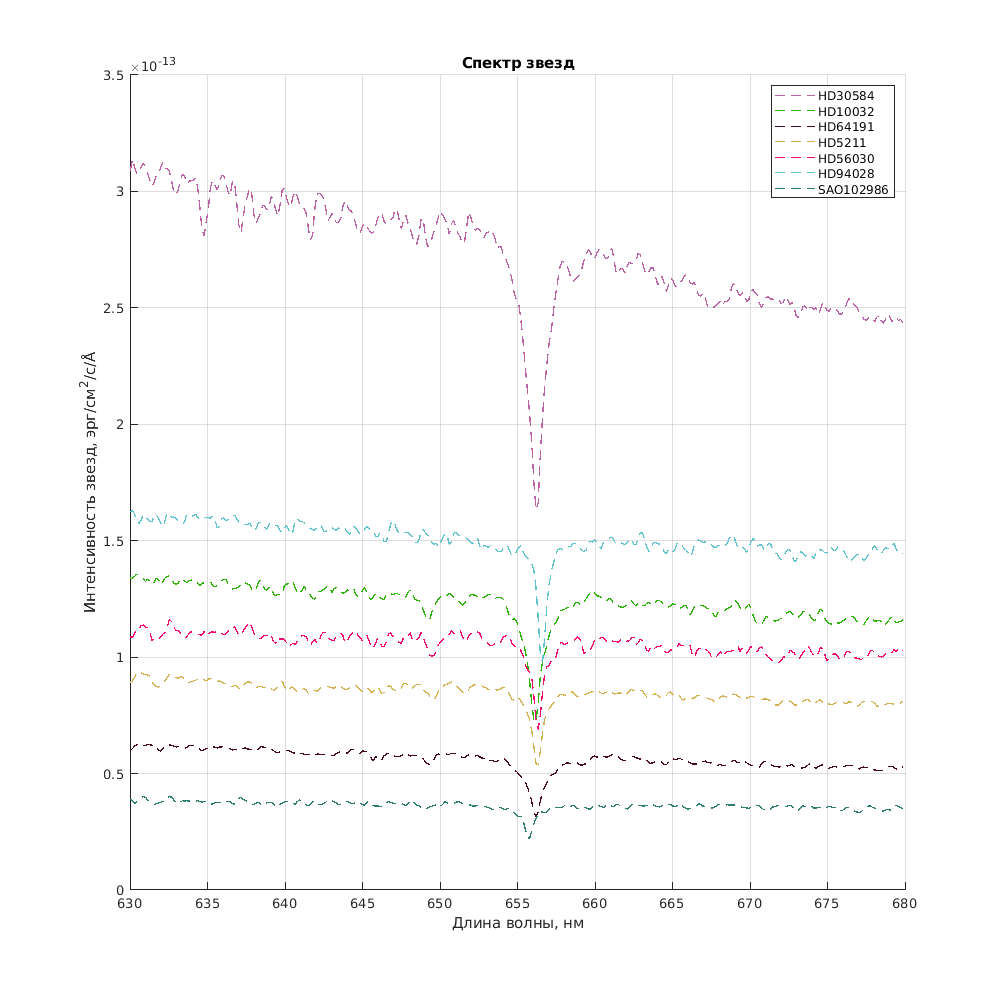

fg1 = figure;

xlabel ('Длина волны, нм');
ylabel (['Интенсивность звезд, эрг/см^2/c/', char (197)]);
title ('Спектр звезд');

set (fg1, 'Position', [0, 0, 1000, 1000])

grid on

hold on
for i = 1: 1 : number_of_stars
    if (z(i) >  0)
        plot (lambda, spectra (:, i),'r', 'LineWidth', 3, 'Color', [rand, rand, rand])
    else
        plot (lambda, spectra (:, i), "b--", 'LineWidth', 1, 'Color', [rand, rand, rand])
    end
end

legend (starNames)

hold off

saveas (fg1, "graph.png")

stars_which_moving_away = starNames (z > 0)


stars_which_moving_away =

  0×1 empty cell array



stars_which_getting_closer = starNames (z < 0)

stars_which_getting_closer = 7×1 cell array
    {'HD30584'  }
    {'HD10032'  }
    {'HD64191'  }
    {'HD5211'   }
    {'HD56030'  }
    {'HD94028'  }
    {'SAO102986'}
